# Radial Basis Function Network

*© *Copyright 2022 The MathWorks, Inc

## `radbas` to compute weighted and shifted Gaussian RBFs

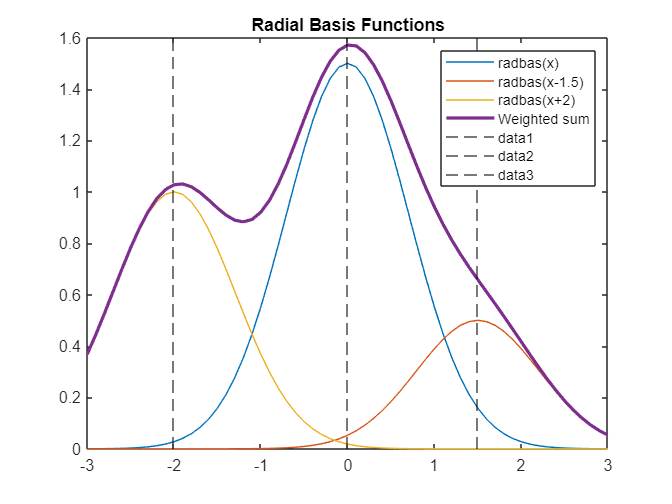

x = -3:.1:3;                             % x = row 1x61 ,
c = [0; 1.5; -2];                        % c = column 3x1
omega = [1.5 0.5 1];                     % omega = row 1x3
a = radbas (x-c);                        % x-c = a matrix 3 x61 ( implicit expansion )

figure
plot(x, omega .*a')                      % plot of 3 wighted RBFs
hold on 
plot(x, omega *a, LineWidth =2) % plot of the sum of the 3 RBF
title('Radial Basis Functions');
legend('radbas(x)','radbas(x-1.5)', 'radbas(x+2)', "Weighted sum")
for i = 1:3, xline(c(i), 'k--'), end